**GRADIENT DESCENT **

%Specifications

a1 = 1;
a2 = 1;
a3 = 1;

X1d = 2 ;
X2d = 1;
X3d = 0; %End effector points

**Gradient Descent with Initial conditions: 0 0 0, rate = 0.1**

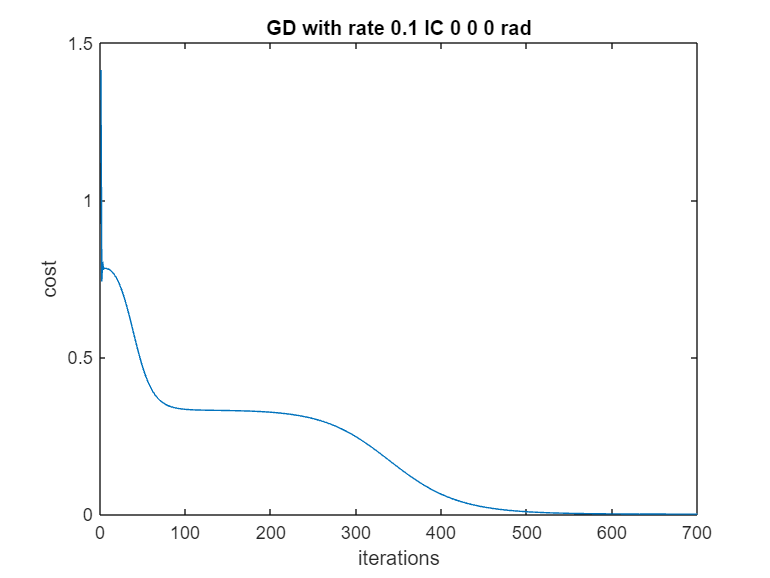

theta_1 = 0.0117

theta_2 = 89.9862

theta_3 = -90.0043

iterations = 700


theta_in_1 = 0;
theta_in_2 = 0;
theta_in_3 = 0; %Starting point angle

rate1 = 1/10;

[theta_1, theta_2 , theta_3, iterations] = GradientDescent(theta_in_1, theta_in_2, theta_in_3, rate1,a1,a2,a3,X1d,X2d,X3d)

**Gradient Descent with Initial conditions: pi/2 pi/2 pi/2, rate = 0.1**

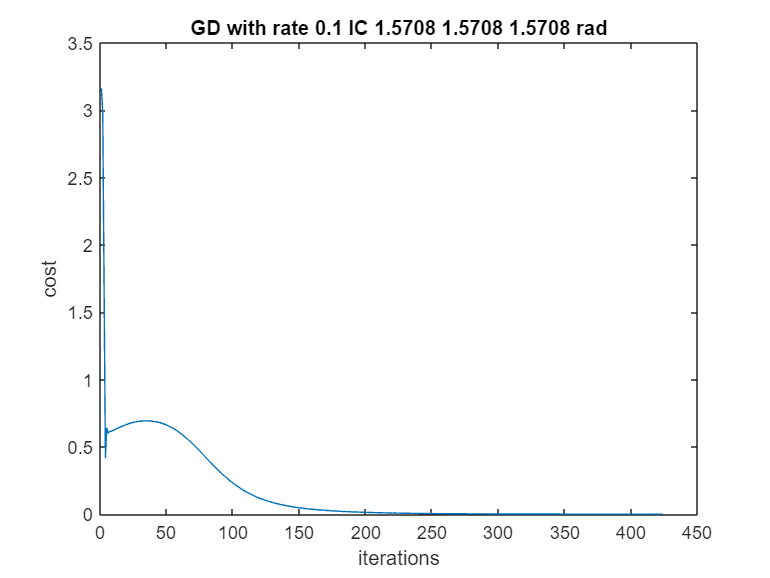

theta_1 = 0.0113

theta_2 = 89.9868

theta_3 = -90.0041

iterations = 424

theta_in_1 = pi/2;
theta_in_2 = pi/2;
theta_in_3 = pi/2; %Starting point angle

[theta_1, theta_2 , theta_3, iterations] = GradientDescent(theta_in_1, theta_in_2, theta_in_3, rate1,a1,a2,a3,X1d,X2d,X3d)

**Gradient Descent with Initial conditions: 0 0 0, rate = 0.5**

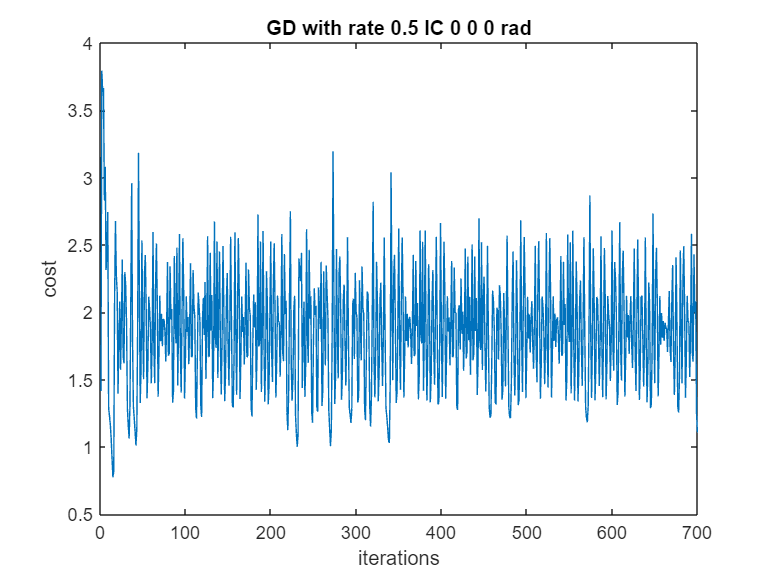

theta_1 = 29.5846

theta_2 = -221.2496

theta_3 = 223.2787

iterations = 700

rate2 = 1/2;

theta_in_1 = 0;
theta_in_2 = 0;
theta_in_3 = 0; %Starting point angle

[theta_1, theta_2 , theta_3, iterations] = GradientDescent(theta_in_1, theta_in_2, theta_in_3, rate2,a1,a2,a3,X1d,X2d,X3d)

**Gradient Descent with Initial conditions: pi/2 pi/2 pi/2, rate = 0.5**

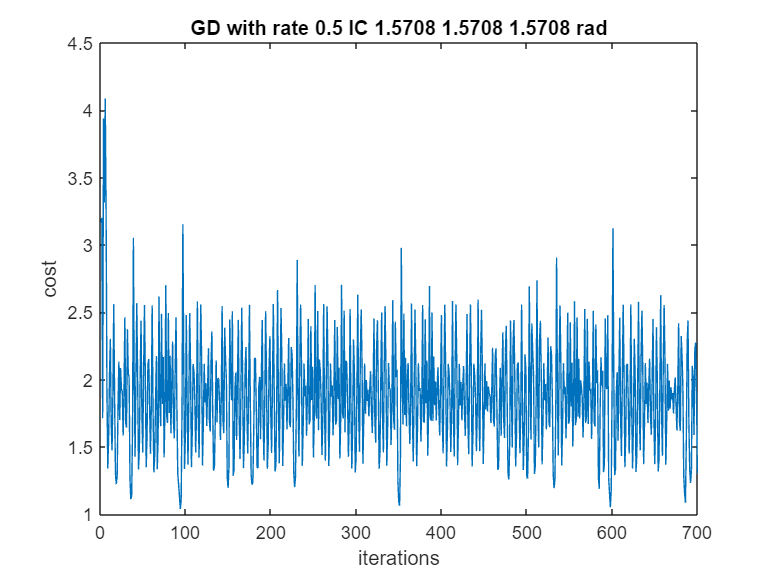

theta_1 = 25.1048

theta_2 = 145.2790

theta_3 = -177.0485

iterations = 700

theta_in_1 = pi/2;
theta_in_2 = pi/2;
theta_in_3 = pi/2; %Starting point angle

[theta_1, theta_2 , theta_3, iterations] = GradientDescent(theta_in_1, theta_in_2, theta_in_3, rate2,a1,a2,a3,X1d,X2d,X3d)

function [theta_1, theta_2, theta_3, iterations] = GradientDescent(theta_in_1, theta_in_2, theta_in_3, rate, a1,a2,a3,X1d,X2d,X3d)
 
 
    % Counter for number of Iterations
    count = 0;
    
    % Calculate Initial starting points using Forward Kinematics
    X1 = a1*cos(theta_in_1) + a2*cos(theta_in_1+theta_in_2) + a3*cos(theta_in_1+theta_in_2+theta_in_3);
    X2 = a1*sin(theta_in_1) + a2*sin(theta_in_1+theta_in_2) + a3*sin(theta_in_1+theta_in_2+theta_in_3);
    X3 = theta_in_1+theta_in_2+theta_in_3;
    
    % Vector matrix of desired location of robotic arm
    end_eff = [X1d;X2d; X3d];
    
    % Vector of starting point of robotic arm
    start_eff = [X1;X2;X3];
    
    % Vector of starting point angle
    theta_eff = [theta_in_1;theta_in_2;theta_in_3];
    
    % Error related to end effector and starting point
    error = start_eff - end_eff;
    
    % Cost function based on euclidean distance of end effector and starting point
    
    cost = sqrt((end_eff(1,1)-start_eff(1,1))^2+(end_eff(2,1)-start_eff(2,1))^2);
    
    
    %array for plotting results
    count_array = zeros(1,1);
    cost_array = zeros(1,1);
    
    
    % Iterating the process and decreasing the cost to reach end end effector
    while (cost >0.0001 && count < 700)
    
        theta_1 = theta_eff(1,1);
        theta_2 = theta_eff(2,1);
        theta_3 = theta_eff(3,1);
        sin1 = sin(theta_1);
        sin12 = sin(theta_1+theta_2);
        sin123 = sin(theta_1+theta_2+theta_3);
        cos1 = cos(theta_1);
        cos12 = cos(theta_1 + theta_2);
        cos123 = cos(theta_1+theta_2+theta_3);
    
        X1 = a1*cos1 + a2*cos12 + a3*cos123;
        X2 = a1*sin1 + a2*sin12 + a3*sin123;
        X3 = theta_1+theta_2+theta_3;
    
        Jacobian = [(-a1*sin1 - a2*sin12 - a3*sin123), (-a2*sin12 - a3*sin123), (-a3*sin123);
            (a1*cos1 + a2*cos12 + a3*cos123), (a2*cos12 + a3*cos123), (a3*cos123);
            1, 1, 1];
    
        start_eff = [X1;X2;X3]; % f(q)
        error = start_eff - end_eff ; % f(q) - xd
        trans_jacob = transpose(Jacobian); % transpose of Jacobian
        theta_eff = theta_eff - (rate)*(trans_jacob)*(error);  % qk+1 = qk-lr*transpose(j)*(f(q)-xd)
        cost = sqrt((end_eff(1,1)-start_eff(1,1))^2+(end_eff(2,1)-start_eff(2,1))^2); % square Euclidean distance
        count = count + 1; % Counting Iterations
    
        count_array(count) = count;
        cost_array(count) = cost;
    
    end

    theta_eff = theta_eff*180/pi;
    
    theta_1 = theta_eff(1);
    theta_2 = theta_eff(2);
    theta_3 = theta_eff(3);
    iterations = count;
    
    plot(count_array, cost_array)
    xlabel('iterations');
    ylabel('cost');
    title(['GD with rate ',num2str(rate),' ', 'IC ', num2str(theta_in_1),' ',num2str(theta_in_2), ' ',num2str(theta_in_3), ' rad'])
end


 

